% Celal AKSOY 

# P,PD,PI Controller Design for DC Motor

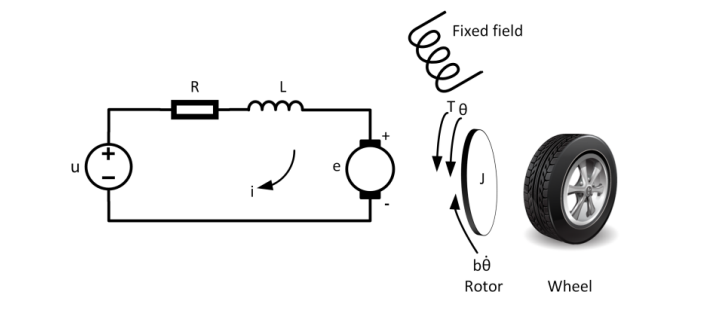

clear all;
clc;

j  = 0.01;    % kg/m^2
b  = 0.1;     % N*m*s
Ke = 0.01;    % V/rad/sec
Kt = 0.01;    % N*m/Amp
R  = 1;       % Ohm
L  = 0.5;     % H
r  = 0.4;     % m

s = tf('s');

Go =((Kt*r)/(L*j)) / (s^2 + ((b*L+R*j)/(L*j))*s + (b*R+Ke*Kt)/(L*j)) % Open loop transfer function

Go =
 
         0.8
  ------------------
  s^2 + 12 s + 20.02
 
Continuous-time transfer function.



syms s 

Gs = 0.8/(s^2+12*s+20.02) %Symbolically generated transfer function for open loop

$$Gs = \frac{4}{5\,\left(s^{2}+12\,s+\frac{1001}{50}\right)}$$

G = feedback(Go,1) % Close loop transfer function

G =
 
         0.8
  ------------------
  s^2 + 12 s + 20.82
 
Continuous-time transfer function.



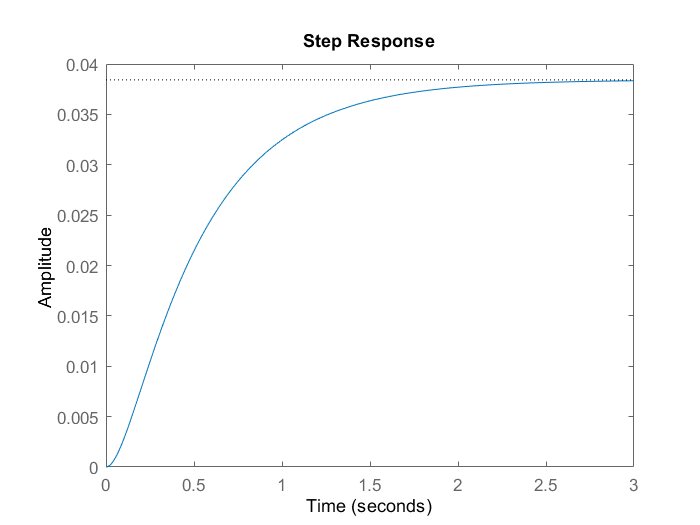

step(G)

stepinfo(G)

ans = struct with fields:
        RiseTime: 1.0847
    SettlingTime: 1.9731
     SettlingMin: 0.0346
     SettlingMax: 0.0384
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0384
        PeakTime: 3.1551


These values will help us predict the behavior of the controllers we will design.

## P Controller Design for DC motor

We were asked to design a P controller that satisfies the required overshoot conditions of less than 20 percent and a settling time of less than 5 seconds. However, we can't operate with a settling time requirement of less than 5 seconds. Because the P controller has no effect on the settling time. Therefore, we expect to see the settling time as equivalent to 'stepinfo(G)' values. This value already meets the demand. Consequently, we will only be concerned with the zeta value.

OverShoot = 0.2;
Pzeta = -log(OverShoot)/sqrt(pi^2+log(OverShoot)^2) % Comes from the overshoot formula

Pzeta = 0.4559

syms Kp Pwn real

Cp=Kp % Our P controller

$$Cp = \mathrm{Kp}$$

Tfde=s^2+2*Pzeta*Pwn*s+Pwn^2; % Transfer function that satisfies the required conditions(desired)

Tfcp=simplify(Cp*Gs/(1+Cp*Gs)) % Applying a controller to our open loop transfer function(Gs)

$$Tfcp = \frac{40\,\mathrm{Kp}}{50\,s^{2}+600\,s+40\,\mathrm{Kp}+1001}$$

% The process of separating the coefficients
[n,d]= numden(Tfcp); 
n= coeffs(n,s,'all'); 
d= coeffs(d,s,'all'); 

d=d/d(1); % The leading coefficient must be 1

%The process of matching the coefficients of the desired function and the characteristic function
prob = d == coeffs(Tfde,s,'all');

% Coefficient digits be max 4
for i=1:length(prob) 
disp(vpa( prob(i),4));
end

$$1.0=1.0$$

$$12.0=0.9119\,\mathrm{Pwn}$$

$$0.8\,\mathrm{Kp}+20.02={\mathrm{Pwn}}^{2}$$

solution = solve(prob); % Solution of the problem but as symbolic

% Process of symbolic to numeric conversion
Pwnv=double(solution.Pwn); 
kpv=double(solution.Kp);

Cp = kpv

Cp = 191.4354

Pwn = Pwnv

Pwn = 13.1593

Tfcp = zpk(Cp*G/(1+Cp*G)) 

Tfcp =
 
       153.15 (s+9.896) (s+2.104)
  -------------------------------------
  (s+9.896) (s+2.104) (s^2 + 12s + 174)
 
Continuous-time zero/pole/gain model.



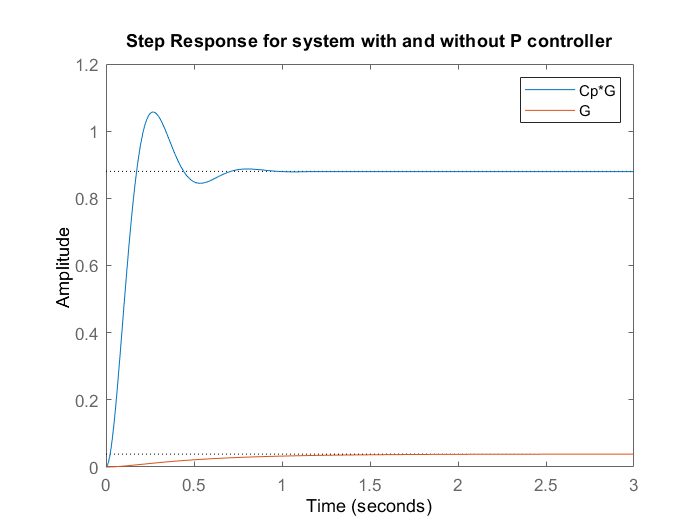

figure % So that it doesn't overwrite the old plot for normal script

step(Tfcp)
hold on
step(G)

title('Step Response for system with and without P controller')
legend('Cp*G','G')

stepinfo(Tfcp)

ans = struct with fields:
        RiseTime: 0.1180
    SettlingTime: 0.6316
     SettlingMin: 0.8242
     SettlingMax: 1.0572
       Overshoot: 20.0913
      Undershoot: 0
            Peak: 1.0572
        PeakTime: 0.2686


As seen from stepinfo(Tfcp) values, settling time and overshoot requirements are met. Rise time also seems to have decreased due to the effect of the P controller on Wn. Also it turns out that the P controller has a slightly reduced effect on settling time due to its effect on wn.

## **PD Controller Design for DC Motor**

In this task, we were asked to design a pd controller with the critical damp, that is, the zeta value of 1

syms Kd z real ;

Cpd = Kd*(s+z) % Our PD controller

$$Cpd = \mathrm{Kd}\,\left(s+z\right)$$

syms s PDwn;

PDzeta = 1; %critical damp value for zeta

Tfde = s^2+2*PDzeta*PDwn*s+PDwn^2;  % Transfer function that satisfies the required conditions(desired)

Tfcpd=simplify(Cpd*Gs/(1+Cpd*Gs)) % Applying a controller to our open loop transfer function(Gs)

$$Tfcpd = \frac{40\,\mathrm{Kd}\,\left(s+z\right)}{600\,s+40\,\mathrm{Kd}\,s+40\,\mathrm{Kd}\,z+50\,s^{2}+1001}$$

% The process of separating the coefficients
[n,d]=numden(Tfcpd);
n=coeffs(n,s,'all');
d= coeffs(d,s,'all');

d=d/d(1); % The leading coefficient must be 1

%The process of matching the coefficients of the desired function and the characteristic function
prob=d==coeffs(Tfde,s,'all');

% Coefficient digits be max 4
for i=1:length(prob)
disp(vpa( prob(i),4));
end

$$1.0=1.0$$

$$0.8\,\mathrm{Kd}+12.0=2.0\,\mathrm{PDwn}$$

$$0.8\,\mathrm{Kd}\,z+20.02={\mathrm{PDwn}}^{2}$$

PDsolution=solve(prob); % Solution of the problem but as symbolic.

%Since there are 2 equations with 3 unknowns, it will give more than one result. Among these results, we must choose the values that are suitable for the conditions.
PDwnv=double(PDsolution.PDwn)

PDwnv =    -1.9967
    7.9983
    4.0017
   13.9967


kdv=double(PDsolution.Kd)

kdv =   -19.9917
    4.9958
   -4.9958
   19.9917


zv=double(PDsolution.z)

zv =     1.0025
   10.9975
    1.0025
   10.9975


% We want our wn value to be positive so that it can be stable. In addition, for the root to be negative in (s+z), the z value must also be positive. But z values are already positive.
kdv=kdv(PDwnv>=0);
zv=zv(PDwnv>=0);
PDwnv=PDwnv(PDwnv>=0);

% Our filtered values
Kd = kdv

Kd =     4.9958
   -4.9958
   19.9917


z = zv

z =    10.9975
    1.0025
   10.9975


PDwn = PDwnv

PDwn =     7.9983
    4.0017
   13.9967


s = tf('s');
Cpd1 = Kd(1)*(s+z(1)) % Our tf of PD(1) controller 

Cpd1 =
 
  4.996 s + 54.94
 
Continuous-time transfer function.



Tfcpd1 = feedback(Cpd1*G,1) % Our transfer function for the first group from the values we obtained. 

Tfcpd1 =
 
   3.997 s + 43.95
  ------------------
  s^2 + 16 s + 64.77
 
Continuous-time transfer function.



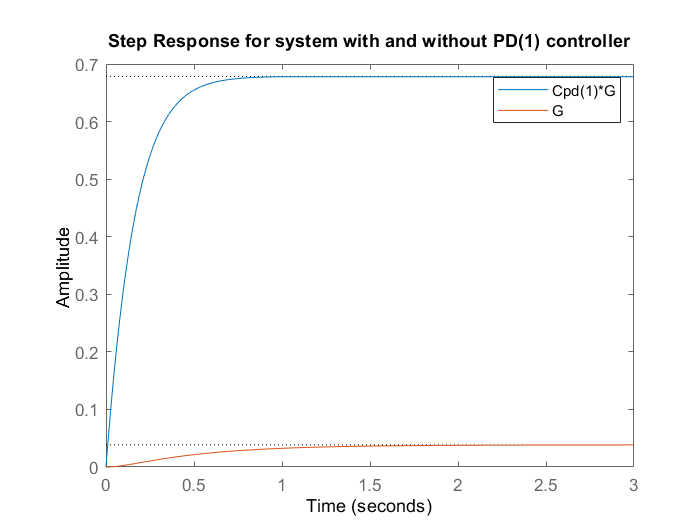

figure 

step(Tfcpd1)
hold on
step(G)

title('Step Response for system with and without PD(1) controller')
legend('Cpd(1)*G','G')

stepinfo(Tfcpd1)

ans = struct with fields:
        RiseTime: 0.3352
    SettlingTime: 0.5779
     SettlingMin: 0.6126
     SettlingMax: 0.6779
       Overshoot: 0
      Undershoot: 0
            Peak: 0.6779
        PeakTime: 0.9730


As seen from Stepinfo(Tfcpd(1)) values, Rise Time and Settling Time of system have decreased. This is because the PD controller affects both wn and sigma. The rise time is decreasing due to wn. Settling time is also reduced due to sigma. As a result, the PD controller has accelerated the system.

Cpd2 = Kd(2)*(s+z(2)) % Our tf of PD(2) controller

Cpd2 =
 
  -4.996 s - 5.008
 
Continuous-time transfer function.



Tfcpd2= feedback(Cpd2*G,1) % Our transfer function for the seceond group from the values we obtained. 

Tfcpd2 =
 
    -3.997 s - 4.007
  ---------------------
  s^2 + 8.003 s + 16.81
 
Continuous-time transfer function.



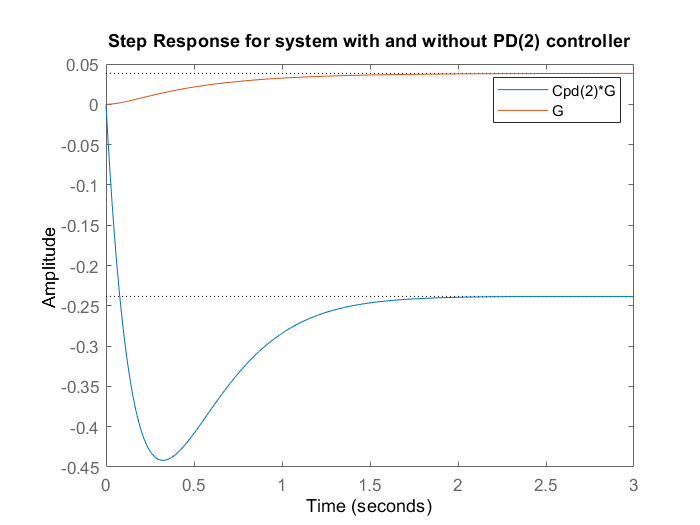

figure 

step(Tfcpd2)
hold on
step(G)

title('Step Response for system with and without PD(2) controller')
legend('Cpd(2)*G','G')

stepinfo(Tfcpd2)

ans = struct with fields:
        RiseTime: 0.0618
    SettlingTime: 1.6388
     SettlingMin: -0.4417
     SettlingMax: -0.2172
       Overshoot: 85.3612
      Undershoot: 0
            Peak: 0.4417
        PeakTime: 0.3222


As can be seen from the table and graph, the system exhibits an undershoot condition. This is because the k coefficient is negative. This is something we don't want.

Cpd3 = Kd(3)*(s+z(3)) % Our tf of PD(3) controller

Cpd3 =
 
  19.99 s + 219.9
 
Continuous-time transfer function.



Tfcpd3 = feedback(Cpd3*G,1) % Our transfer function for the third group from the values we obtained.

Tfcpd3 =
 
     15.99 s + 175.9
  ---------------------
  s^2 + 27.99 s + 196.7
 
Continuous-time transfer function.



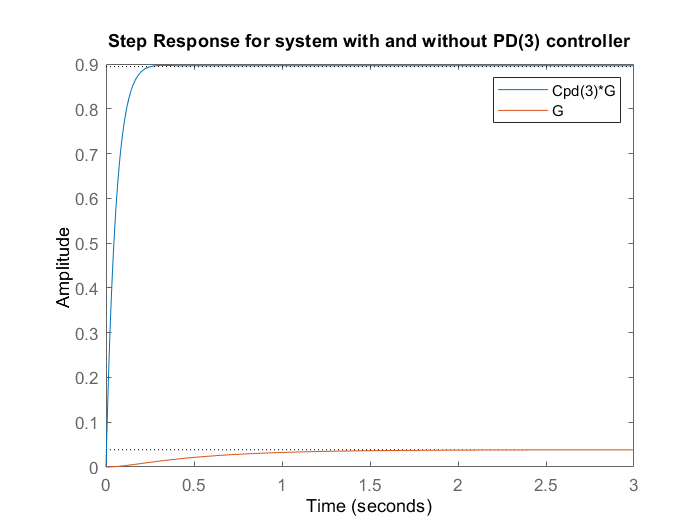

figure 

step(Tfcpd3)
hold on
step(G)

title('Step Response for system with and without PD(3) controller')
legend('Cpd(3)*G','G')

stepinfo(Tfcpd3)

ans = struct with fields:
        RiseTime: 0.1134
    SettlingTime: 0.1855
     SettlingMin: 0.8093
     SettlingMax: 0.8969
       Overshoot: 0.3051
      Undershoot: 0
            Peak: 0.8969
        PeakTime: 0.3224


If we compare it with the first PD system, PD system we obtained with the third group values is faster. Here we see that the kpd coefficient is increasing. This has caused this effect because both derivative and proportional value have common coefficients.

## PI Controller Design **for DC Motor**

We were asked to design a P controller that satisfies the required overshoot conditions of less than 20 percent and a settling time of less than 5 seconds. However, here we must consider that both conditions are affected by the PI controller.

syms s Kpi P zpi Piwn Pizeta

Cpi=(Kpi*(s+zpi))/s  % Our PI controller

$$Cpi = \frac{\mathrm{Kpi}\,\left(s+\mathrm{zpi}\right)}{s}$$

Tfcpi=simplify(Cpi*Gs/(1+Cpi*Gs)) % Applying a controller to our open loop transfer function(Gs)

$$Tfcpi = \frac{40\,\mathrm{Kpi}\,\left(s+\mathrm{zpi}\right)}{1001\,s+40\,\mathrm{Kpi}\,s+40\,\mathrm{Kpi}\,\mathrm{zpi}+600\,s^{2}+50\,s^{3}}$$

% The process of separating the coefficients
[n,d]= numden(Tfcpi);
d=coeffs(d,s,'all');
d=d/d(1); %The leading coefficient must be 1

In this system, if the wn value is taken as an unknown, 3 equations with 4 unknowns are obtained. Instead of giving more than one result, Matlab itself provides the equation but gives nonsense values. Therefore, by assigning a logical value to Wn that satisfies the conditions, we obtain 3 equations with 3 unknowns and reach the result. It also meets all the requirements.

Pizeta = Pzeta;

settling = 1; % 'Settling time <5' and 'Overshoot<20' conditions provided
sigma = 4 /settling;
Piwn = sigma/Pizeta;

Pizeta = Pzeta;
Tfde = s^2+2*Pizeta*Piwn*s+Piwn^2; % Transfer function that satisfies the required conditions(desired)

We need to add one more root to make the coefficients of our desired polynomial equal to the coefficients of our characteristic equation.

Tfde3 = Tfde*(s+P);

%The process of matching the coefficients of the desired function and the characteristic function
prob=d==coeffs(Tfde3,s,'all');

% Coefficient digits be max 4
for i=1:length(prob)
disp(vpa( prob(i),4));
end

$$1.0=1.0$$

$$12.0=P+8.0$$

$$0.8\,\mathrm{Kpi}+20.02=8.0\,P+76.96$$

$$0.8\,\mathrm{Kpi}\,\mathrm{zpi}=76.96\,P$$

solution=solve(prob); % Solution of the problem but as symbolic

kpiv=double(solution.Kpi)

kpiv = 111.1796

zpiv=double(solution.zpi)

zpiv = 3.4612

Pv=double(solution.P)

Pv = 4

Kpi = kpiv;
zpi = zpiv;

s = tf('s');
Cpi = Kpi*(s+zpiv)/s % Our PI controller

Cpi =
 
  111.2 s + 384.8
  ---------------
         s
 
Continuous-time transfer function.



Tfcpi = zpk(Cpi*G/(1+Cpi*G)) % Our closed loop transfer function

Tfcpi =
 
                                                
          88.944 s (s+9.896) (s+3.461) (s+2.104)
                                                
  ------------------------------------------------------
                                                        
  s (s+9.896) (s+3.948) (s+2.104) (s^2 + 8.052s + 77.97)
                                                        
                                                        
 
Continuous-time zero/pole/gain model.



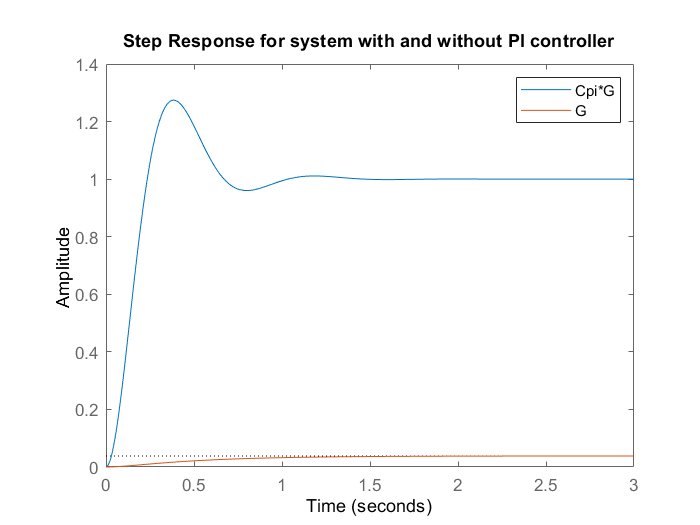

figure 
step(Tfcpi)
hold on
step(G)

title('Step Response for system with and without PI controller')
legend('Cpi*G','G')

stepinfo(Tfcpi)

ans = struct with fields:
        RiseTime: 0.1594
    SettlingTime: 0.9315
     SettlingMin: 0.9485
     SettlingMax: 1.2745
       Overshoot: 27.4505
      Undershoot: 0
            Peak: 1.2745
        PeakTime: 0.3849


We see that the Rise Time and Settling Time are significantly reduced due to the effect of the PI controller on sigma and wn. It also meets all the requirements.

## Comparison of All

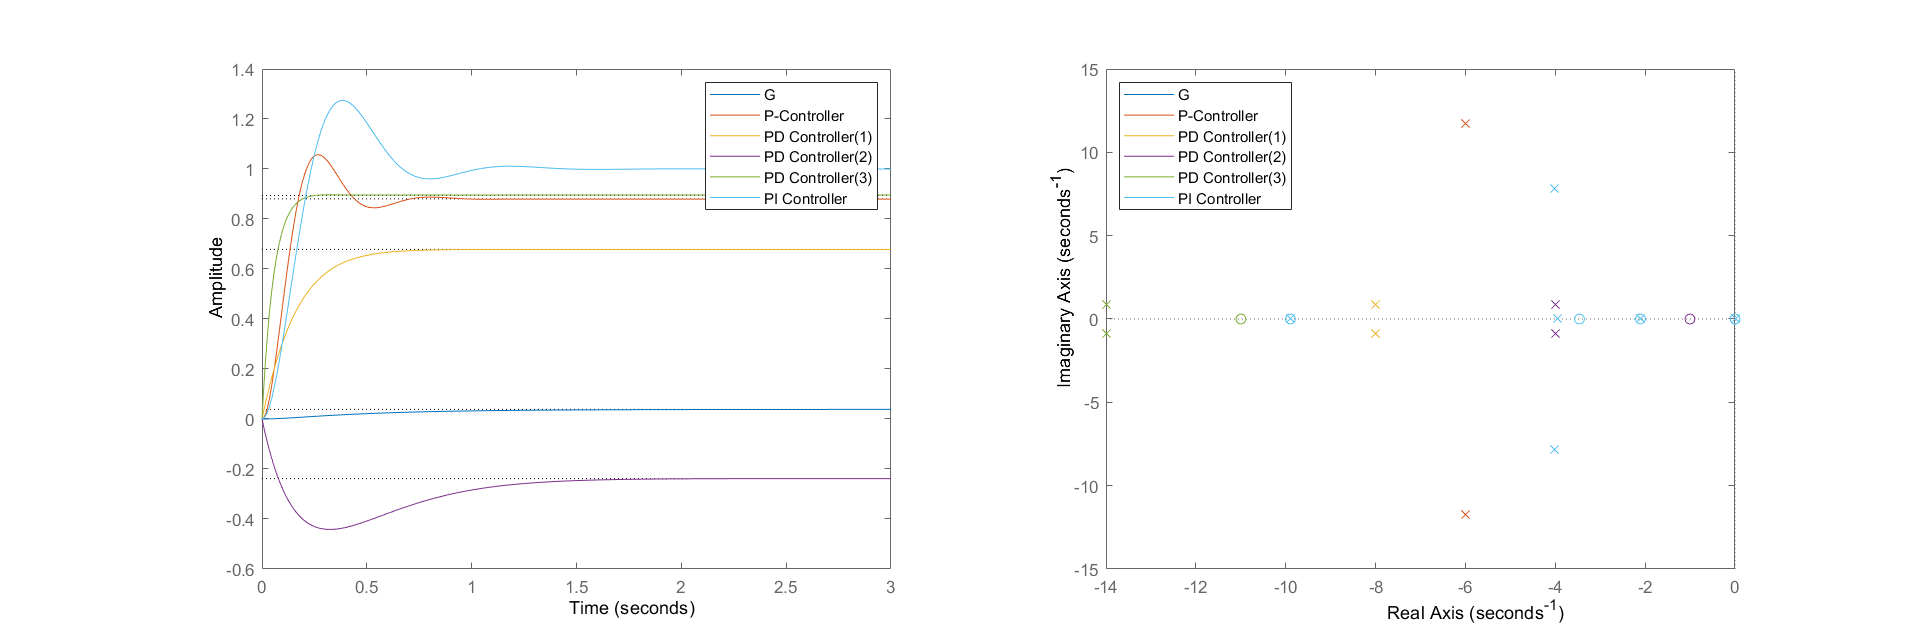

figure('Position', [0 0 1800 600]) 

subplot(1,2,1)
step(G)
hold on
step(Tfcp)
step(Tfcpd1)
step(Tfcpd2)
step(Tfcpd3)
step(Tfcpi)
legend('G','P-Controller', 'PD Controller(1)','PD Controller(2)','PD Controller(3)', 'PI Controller')
title('G,P,PD,PI with Step')

subplot(1,2,2)
pzmap(G)
hold on
pzmap(Tfcp)
pzmap(Tfcpd1)
pzmap(Tfcpd2)
pzmap(Tfcpd3)
pzmap(Tfcpi)
legend('G','P-Controller', 'PD Controller(1)','PD Controller(2)','PD Controller(3)', 'PI Controller')
legend('Location','northwest')

If we talk about these results, we need to talk about the PD controller separately. Because the desired situation in the PD controller was different from the P and PI controller. However, it can be said that the PD controller accelerates the system due to derivative effects. But when a type 0 system and step is applied, a steady state error is received. As for the P and PI controller, we see that the P controller has a huge impact on the amplitude. But P controller is also a type 0 system and there is still a steady state error. The PI controller, on the other hand, is slower, but it both provides the conditions and eliminates the steady state error. We can attribute this to the fact that it is a step applied type 1 system.

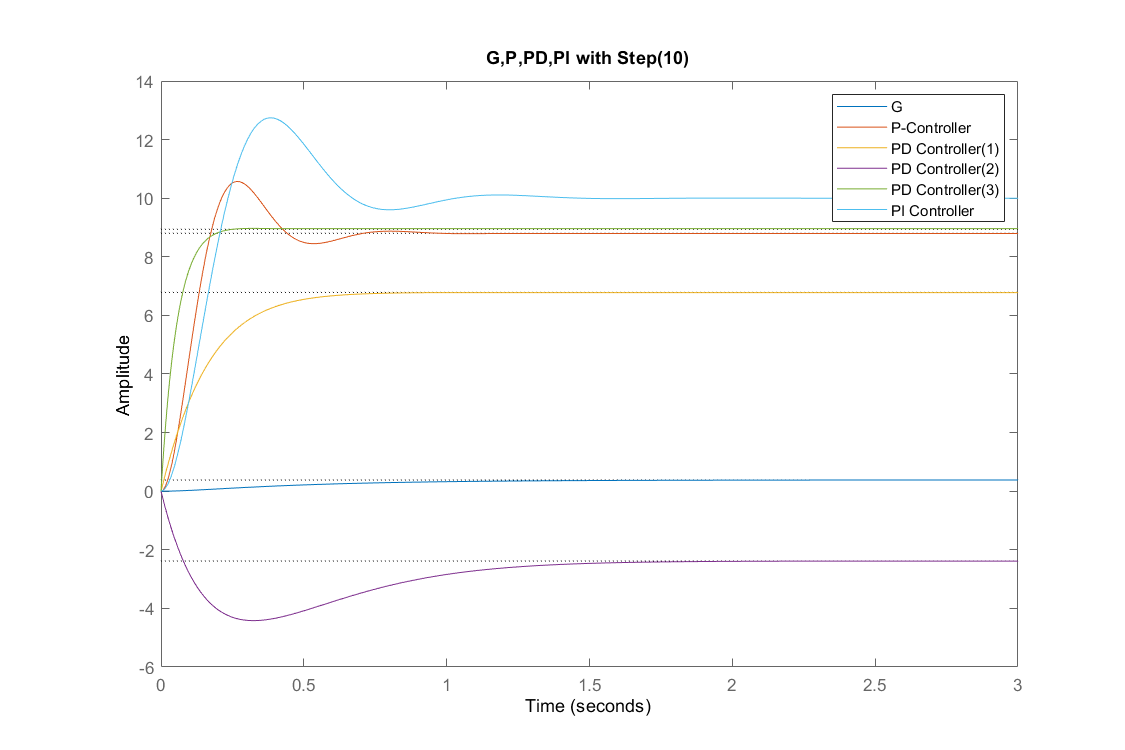

options = stepDataOptions('StepAmplitude', 10);

figure ('Position', [0 0 900 600])

step(G,options)
hold on
step(Tfcp,options)
step(Tfcpd1,options)
step(Tfcpd2,options)
step(Tfcpd3,options)
step(Tfcpi,options)
legend('G','P-Controller', 'PD Controller(1)','PD Controller(2)','PD Controller(3)', 'PI Controller')
title('G,P,PD,PI with Step(10)')

stepG = step(G,options);
stepinfo(stepG)

ans = struct with fields:
        RiseTime: 114.5122
    SettlingTime: 202.6091
     SettlingMin: 0.3444
     SettlingMax: 0.3825
       Overshoot: 0
      Undershoot: 0
            Peak: 0.3825
        PeakTime: 288


When we apply a 10 sec step function to the system, we see that the amplitude of 1 increases 10 times. Therefore, the final value of the system has increased 10 times. Apart from this situation, when we look at the 'stepinfo' function, we see that the system has slowed down considerably.